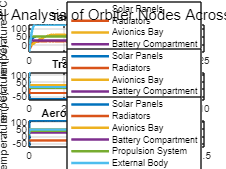

clear; clc;

sBoltzmann = 5.670e-8; % (W/m^2K^4)
SolarFlux_Earth = 1400; 
SolarFlux_Space = 600; 
SolarFlux_Mars = 589; 
Albedo_Earth = 0.3;  
Albedo_Mars = 0.25;

T_mars = 210; 
T_space = 2.7;  
T_earth = 290; 

nodes = {'Solar Panels', 'Radiators', 'Avionics Bay', 'Battery Compartment', 'Propulsion System', 'External Body'};
Area = [2.0; 0.9; 0.8; 0.5; 1.0; 1.5]; 
absorb = [0.1; 0.02; 0.05; 0.3; 0.4; 0.5]; 
emissivity = [0.75; 0.8; 0.15; 0.6; 0.75; 0.8];

power = [0; 0; 0; 0; 0; 0]; 

internal_heating = [12; 16; 22; 12; 17; 6];

% active TCS
kapton_patch_heaters = [5; 0; 3; 4; 0; 3];
radioisotope_heaters = [0; 0; 4; 4; 0; 0];
ricor_cryocoolers     = [1; 1; 2; 0; 1; 4];
thermal_sensors       = [1; 1; 1; 1; 1; 0];

internal_heating = internal_heating + kapton_patch_heaters + ...
                   radioisotope_heaters + ricor_cryocoolers + ...
                   thermal_sensors;

massNode = [10; 5; 8; 6; 12; 15]; 
c_p = 900; 
C = massNode * c_p;

% updated ranges
op_range = [123.15 373.15;   % Solar Panels (-150 to 100)
            243.15 313.15;   % Radiators (-30 to 40)
            263.15 323.15;   % Avionics Bay (-10 to 50)
            273.15 288.15;   % Battery (0 to 15)
            253.15 313.15;   % Propulsion System (-20 to 40)
            153.15 378.15];  % External Body (-120 to 105)

survival_range = [93.15 393.15;    % Solar Panels (-180 to 120)
                  243.15 323.15;   % Radiators (-30 to 50)
                  253.15 333.15;   % Avionics Bay (-20 to 60)
                  253.15 298.15;   % Battery (-20 to 25)
                  243.15 323.15;   % Propulsion System (-30 to 50)
                  133.15 393.15];  % External Body (-140 to 120)

% initial
T_initial = [250, 240, 260, 270, 260, 230];

% 
time_takeoff = [0, 24 * 3600];       
time_transit = [0, 9 * 30 * 24 * 3600];  
time_aero = [0, 42 * 24 * 3600]; 

Q_absorbEarth = Area .* absorb .* SolarFlux_Earth;
Q_reflectEarth = Area .* absorb .* SolarFlux_Earth * Albedo_Earth;
Q_planetaryEarth = Area .* emissivity .* sBoltzmann .* T_earth^4;
convective_loss = 20 * Area;

thermalBalanceTakeoff = @(t, T) ((Q_absorbEarth + Q_reflectEarth + Q_planetaryEarth + power) - ...
                                  (Area .* emissivity .* sBoltzmann .* (T.^4)) - convective_loss) ./ C;
[t1, T1] = ode45(@(t, T) reshape(thermalBalanceTakeoff(t, T), [], 1), time_takeoff, T_initial);

Q_absorbSpace = Area .* absorb .* SolarFlux_Space;
Q_reflectSpace = 0; 
Q_planetarySpace = Area .* emissivity .* sBoltzmann .* T_space^4; 

thermalBalanceSpace = @(t, T) ((Q_absorbSpace + Q_reflectSpace + Q_planetarySpace + power + internal_heating) - ...
                               (Area .* emissivity .* sBoltzmann .* (T.^4))) ./ C;
[t2, T2] = ode45(@(t, T) reshape(thermalBalanceSpace(t, T), [], 1), time_transit, T1(end, :));

Q_absorbMars = Area .* absorb .* SolarFlux_Mars;
Q_reflectMars = Area .* absorb .* SolarFlux_Mars * Albedo_Mars;
Q_planetaryMars = Area .* emissivity .* sBoltzmann .* T_mars^4; 

power_aero = power;
power_aero(1) = power_aero(1) + 1500;

thermalBalanceAero = @(t, T) ((Q_absorbMars + Q_reflectMars + Q_planetaryMars + power_aero + internal_heating) - ...
                              (Area .* emissivity .* sBoltzmann .* (T.^4))) ./ C;
[t3, T3] = ode45(@(t, T) reshape(thermalBalanceAero(t, T), [], 1), time_aero, T2(end, :));

clamp_to_survival = @(Tmat) min(max(Tmat, survival_range(:,1)'), survival_range(:,2)');
T1 = clamp_to_survival(T1);
T2 = clamp_to_survival(T2);
T3 = clamp_to_survival(T3);

T1_Celsius = T1 - 273.15;
T2_Celsius = T2 - 273.15;
T3_Celsius = T3 - 273.15;

figure;
subplot(3,1,1);
plot(t1 / 3600, T1_Celsius, 'LineWidth', 2);
xlabel('Time (hours)'); ylabel('Temperature (°C)');
title('Takeoff Phase (24 Hours)'); legend(nodes, 'Location', 'Best'); grid on;

subplot(3,1,2);
plot(t2 / (30 * 24 * 3600), T2_Celsius, 'LineWidth', 2);
xlabel('Time (months)'); ylabel('Temperature (°C)');
title('Transit Phase (9 Months)'); legend(nodes, 'Location', 'Best'); grid on;

subplot(3,1,3);
plot(t3 / (30 * 24 * 3600), T3_Celsius, 'LineWidth', 2);
xlabel('Time (months)'); ylabel('Temperature (°C)');
title('Aerobraking Phase (42 days)'); legend(nodes, 'Location', 'Best'); grid on;

sgtitle('Transient Thermal Analysis of Orbiter Nodes Across Mission Phases');


T_all = {T1, T2, T3};
phases = {'Takeoff', 'Transit', 'Aerobraking'};
for p = 1:3
    T_phase = T_all{p};
    for i = 1:length(nodes)
        T_node = T_phase(:, i);
        minT = min(T_node); maxT = max(T_node);
        if minT < survival_range(i,1) || maxT > survival_range(i,2)
            fprintf('[%s Phase] WARNING: %s out of survival range (%.2f°C to %.2f°C), Temp range: %.2f°C to %.2f°C\n', ...
                    phases{p}, nodes{i}, survival_range(i,1)-273.15, survival_range(i,2)-273.15, ...
                    minT-273.15, maxT-273.15);
        elseif minT < op_range(i,1) || maxT > op_range(i,2)
            fprintf('[%s Phase] ALERT: %s out of operational range (%.2f°C to %.2f°C), Temp range: %.2f°C to %.2f°C\n', ...
                    phases{p}, nodes{i}, op_range(i,1)-273.15, op_range(i,2)-273.15, ...
                    minT-273.15, maxT-273.15);
        end
    end
end

[Takeoff Phase] ALERT: Avionics Bay out of operational range (-10.00°C to 50.00°C), Temp range: -13.15°C to 60.00°C
[Takeoff Phase] ALERT: Battery Compartment out of operational range (0.00°C to 15.00°C), Temp range: -3.15°C to 25.00°C
[Takeoff Phase] ALERT: Propulsion System out of operational range (-20.00°C to 40.00°C), Temp range: -13.15°C to 50.00°C
[Takeoff Phase] ALERT: External Body out of operational range (-120.00°C to 105.00°C), Temp range: -43.15°C to 120.00°C
[Transit Phase] ALERT: Avionics Bay out of operational range (-10.00°C to 50.00°C), Temp range: 28.05°C to 60.00°C
[Transit Phase] ALERT: Battery Compartment out of operational range (0.00°C to 15.00°C), Temp range: 11.07°C to 25.00°C
[Transit Phase] ALERT: Propulsion System out of operational range (-20.00°C to 40.00°C), Temp range: 6.20°C to 50.00°C
[Transit Phase] ALERT: External Body out of operational range (-120.00°C to 105.00°C), Temp range: 13.76°C to 120.00°C
[Aerobraking Phase] ALERT: Solar Panels out of ope